q = 2

q = 2


syms s t

g = 2*sin(3*t)

$$g = 2\,\sin\left(3\,t\right)$$

Wo = 1/(s^2-q)

$$Wo = \frac{1}{s^{2}-2}$$

[WoNum, WoDen] = numden(Wo)

$$WoNum = 1$$

$$WoDen = s^{2}-2$$

[WgNum, WgDen] = numden(laplace(g))

$$WgNum = 6$$

$$WgDen = s^{2}+9$$


syms c c0
WrDen = c * WgDen * (s+c0)

$$WrDen = c\,\left(s^{2}+9\right)\,\left(c_{0}+s\right)$$


syms c1 c2 c3 c4 
WrNum = c1*s^3 + c2*s^2 + c3*s + c4

$$WrNum = c_{1}\,s^{3}+c_{2}\,s^{2}+c_{3}\,s+c_{4}$$

pol = coeffs(WrNum*WoNum+ WrDen*WoDen, s, 'All')

$$pol = \left(\begin{array}{cccccc} c & c\,c_{0} & 7\,c+c_{1} & c_{2}+7\,c\,c_{0} & c_{3}-18\,c & c_{4}-18\,c\,c_{0} \end{array}\right)$$


neededPol = coeffs((s+1)*(s+1)*(s+1)*(s+1)*(s+1), s, 'All')

$$neededPol = \left(\begin{array}{cccccc} 1 & 5 & 10 & 10 & 5 & 1 \end{array}\right)$$

sol = solve(pol == neededPol)

sol = struct with fields:
     c: 1
    c0: 5
    c1: 3
    c2: -25
    c3: 23
    c4: 91



WrNumSol = sym2poly(subs(WrNum, [c c0 c1 c2 c3 c4], [sol.c sol.c0 sol.c1 sol.c2 sol.c3 sol.c4 ]))

WrNumSol =      3   -25    23    91


WrDenSol = sym2poly(subs(WrDen, [c c0], [sol.c sol.c0]))

WrDenSol =      1     5     9    45



simtime = 30

simtime = 30


first = sim("Task7.slx", simtime)

first =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                      g: [1x1 timeseries] 
                   tout: [30001x1 double] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


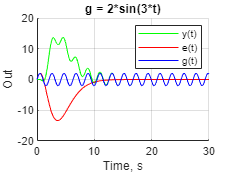

hold on
plot(first.y.Time, first.y.Data, 'green')
plot(first.e.Time, first.e.Data, 'red')
plot(first.g.Time, first.g.Data, 'blue')

xlabel("Time, s")
ylabel("Out")
grid on
title('g = 2*sin(3*t)')
legend("y(t)", "e(t)", "g(t)")